19AIE201

# **Forward and Inverse Analysis of Kuka KR 5**

-Aaditya jain : CB.EN.U4AIE19001

-Advaith Das Maharana : CB.EN.U4AIE19006

-Anirudh Bhaskar: CB.EN.U4AIE19007

-Anuvarshini : CB.EN.U4AIE19012

-Rohith Ramakrishnan : CB.EN.U4AIE19052

## Forward Kinematics :

Given a set of Arm of angles we are to compute the End Effector Coordinates:

Consider $\Theta_1 =0^o$ , $\Theta_2 ={90}^o$ , $\Theta_3 =0^o$ , $\Theta_4 =0^o$ , $\Theta_5 ={270}^o$ and $\Theta_6 ={180}^o$

a = FK([0,90,0,0,270,-180])

a =            1           0           0         800
           0          -1           0           0
           0           0          -1        1005
           0           0           0           1


This output was crosschecked with RoboAnalyser.

i = [a(1:3,4);rad2deg(tr2rpy(a(1:3,1:3),'zyx'))']'

i =          800           0        1005         180           0           0


The following corresponds to the same output in the format x,y,z,$\alpha ,\beta ,\gamma$ 


$$\begin{array}{l}
\alpha -\textrm{Roll}\\
\beta \;-\textrm{Pitch}\\
\gamma -\textrm{Yaw}
\end{array}$$


Corresponding x y z are in mm.

## Inverse Kinematics :

Given a set of End Effector Coordinates we are to compute the corresponding arm angles

Lets consider the output of the Forward Kinematics, these coordinates in the x,y,z,$\alpha ,\beta ,\gamma$ are loaded. 

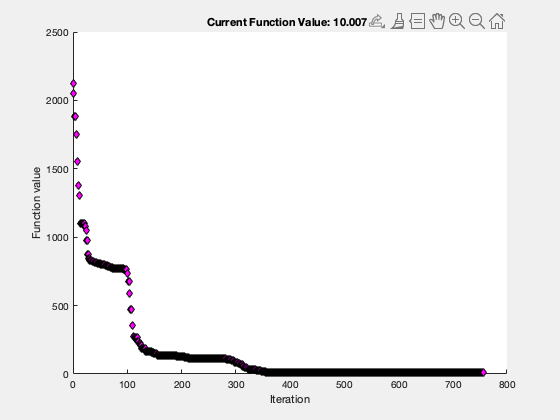

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 10.007481 



I =    -0.7638   90.0955   -6.0210    6.0621  269.2433  177.2424


I = IK_fast_eaxm(i)

figure

For confirmation, lets load these output angles in FK again

a = FK(I);
i = [a(1:3,4);rad2deg(tr2rpy(a(1:3,1:3),'zyx'))']'

i = 	1.0e+03 *

    0.8006    0.0020    1.0054    0.1800   -0.0009    0.0020


## Visual Representation of Forward Kinematics

Loading a CSV defind with Arm angles:

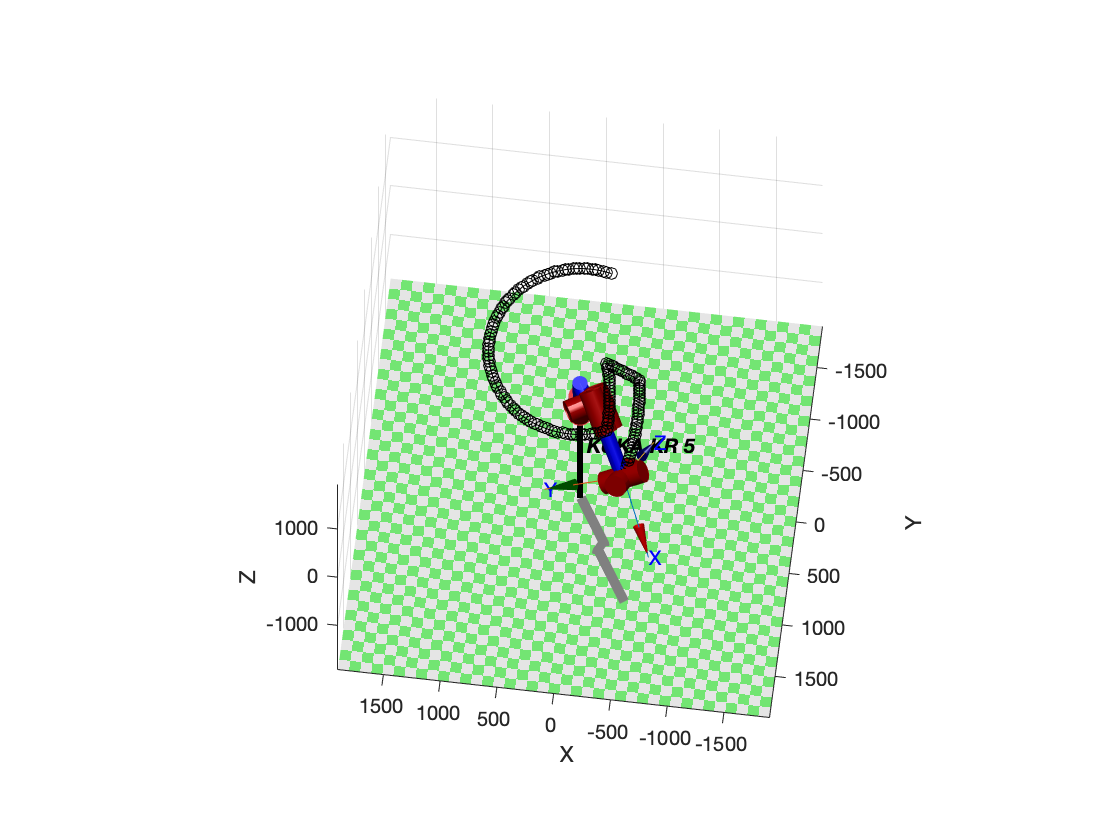

L1 = Link('d',400,'a',180,'alpha',pi/2);
L2 = Link('d',0,'a',600,'alpha',pi/2);
L3 = Link('d',0,'a',120,'alpha',0);
L4 = Link('d',620,'a',0,'alpha',pi/2);
L5 = Link('d',0,'a',0,'alpha',pi/2);
L6 = Link('d',0,'a',0,'alpha',0);

K = SerialLink([L1 L2 L3 L4 L5 L6],'name','KUKA KR 5');
K1 = SerialLink([L1 L2 L3 L4 L5 L6],'name','KUKA KR 5');
A1 = csvread("gdhobara.csv");
t = deg2rad(A1);
%K.model3d = 'KUKA/KR5_arc';
plot(K,t,'trail','-ko')

The previously loaded csv consists of Arm Angles in degrees, to test the inverse we compute the coordinates using the angles and export the same.

Loading a CSV defind with End-Effector Coordinates:

Using the Computed Coordinates we use our Inverse Kinematics algorithm for computing the Arm angles again.

figure

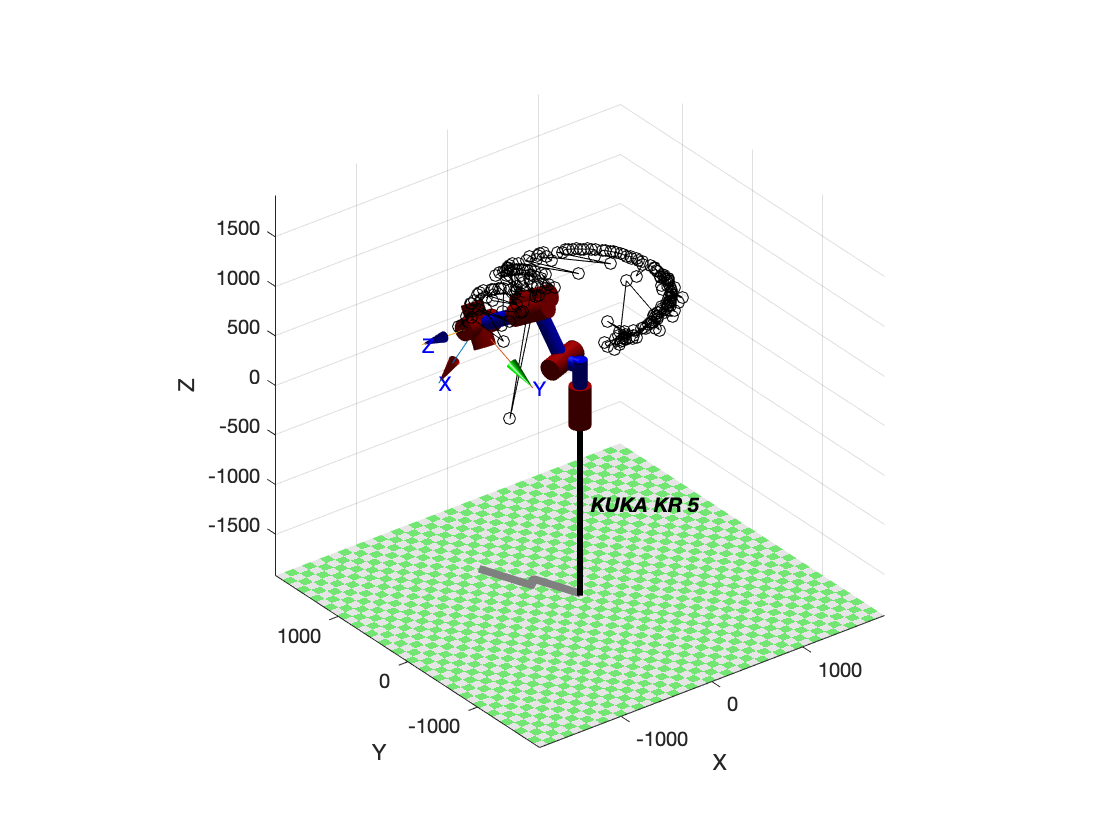

A = csvread("angles_from_IK.csv");
t = deg2rad(A);
%K.model3d = 'KUKA/KR5_arc';
plot(K1,t,'trail','-ko')

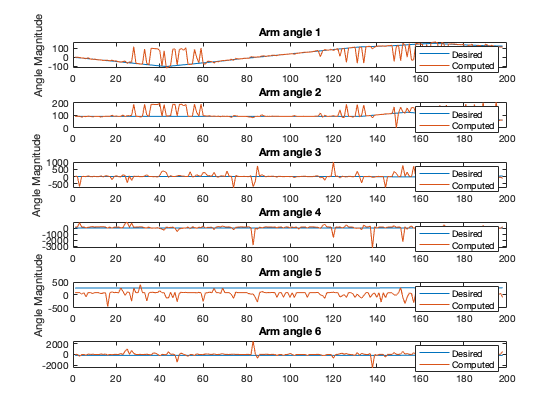

figure
IK = A;
T1=IK(:,1);
T2=IK(:,2);
T3=IK(:,3);
T4=IK(:,4);
T5=IK(:,5);
T6=IK(:,6);


file='gdhobara.csv';
A1=csvread(file);
t1=A1(:,1);
t2=A1(:,2);
t3=A1(:,3);
t4=A1(:,4);
t5=A1(:,5);
t6=A1(:,6);
subplot(6,1,1)
plot(t1)
hold on
plot(T1)
ylabel("Angle Magnitude")
legend("Desired","Computed")
title('Arm angle 1')
subplot(6,1,2)
plot(t2)
hold on
plot(T2)
%ylabel("Angle Magnitude")
legend("Desired","Computed")
title('Arm angle 2')
subplot(6,1,3)
plot(t3)
hold on
plot(T3)
ylabel("Angle Magnitude")
legend("Desired","Computed")
title('Arm angle 3')
subplot(6,1,4)
plot(t4)
hold on
plot(T4)
%ylabel("Angle Magnitude")
legend("Desired","Computed")
title('Arm angle 4')
subplot(6,1,5)
plot(t5)
hold on
plot(T5)
ylabel("Angle Magnitude")
legend("Desired","Computed")
title('Arm angle 5')
subplot(6,1,6)
plot(t6)
hold on
plot(T6)
%ylabel("Angle Magnitude")
legend("Desired","Computed")
title('Arm angle 6')

L1 = Link('d',400,'a',180,'alpha',pi/2);
L2 = Link('d',0,'a',600,'alpha',pi/2);
L3 = Link('d',0,'a',120,'alpha',0);
L4 = Link('d',620,'a',0,'alpha',pi/2);
L5 = Link('d',0,'a',0,'alpha',pi/2);
L6 = Link('d',0,'a',0,'alpha',0);

K = SerialLink([L1 L2 L3 L4 L5 L6],'name','KUKA KR 5');
T1=-55

T1 = -55

T2=90

T2 = 90

T3=52

T3 = 52

T4=0

T4 = 0

T5=270

T5 = 270

T6=-180

T6 = -180

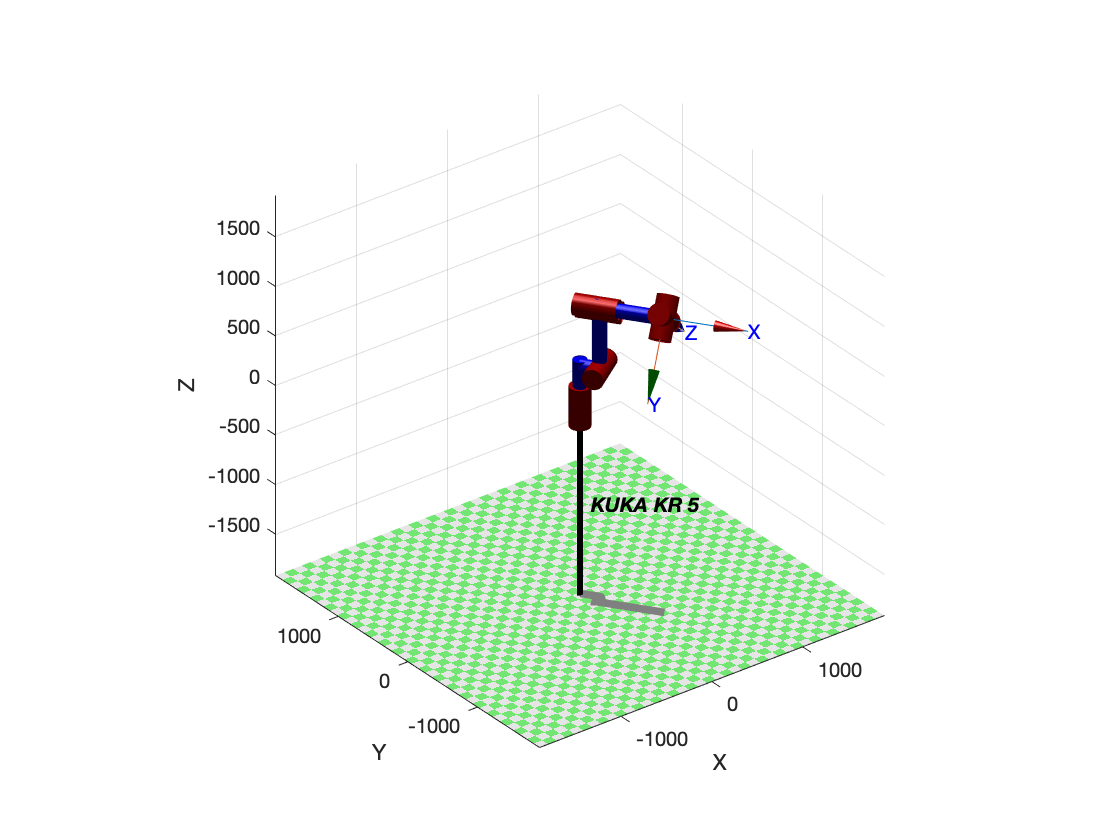

A1 = [T1,T2,T3,T4,T5,T6];
t = deg2rad(A1);
%K.model3d = 'KUKA/KR5_arc';
plot(K,t,'trail','-ko')

function T = FK(a)
q1 = a(1);q2=a(2);q3=a(3);q4=a(4);q5=a(5);q6=a(6);

b1 = 400 ; a1 = 180 ; al1 = deg2rad(90);
b2 = 0   ; a2 = 600 ; al2 = deg2rad(90) ;
b3 = 0   ; a3 = 120 ; al3 = deg2rad(0);
b4 = 620 ; a4 = 0   ; al4 = deg2rad(90); 
b5 = 0   ; a5 = 0   ; al5 = deg2rad(90);
b6 = 115 ; a6 = 0   ; al6 = deg2rad(0) ;

T = H(q1,al1,a1,b1) * H(q2,al2,a2,b2) * H(q3,al3,a3,b3) * H(q4,al4,a4,b4) * H(q5,al5,a5,b5) * H(q6,al6,a6,b6);
end

function a = H(q,al,a,d)
a = (transl(0,0,d)*trotz(q,'deg'))*(transl(a,0,0)*trotx(al));
end

function x = IK_fast_eaxm(i)

th = randi(100,1,6);
a = @(X)fitness(i,X);
options = optimset('PlotFcns',@optimplotfval);
x = fminsearch(a,th,options);
end

function y = fitness(i,x)
    a = FK(x);
    p = [a(1:3,4);rad2deg(tr2rpy(a(1:3,1:3),'zyx'))']';
    del_e = i - p;
    y = norm(del_e + 2*ones(length(del_e)));
end